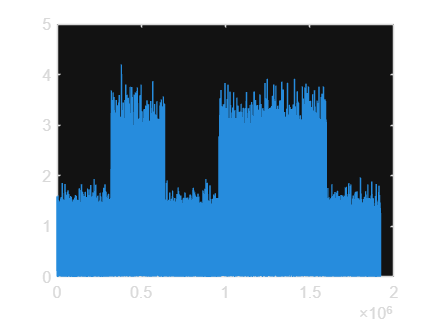

clear all;
clc;
% Constant parameters:
s.N = 1024;
s.Fs = 240e6;
s.Ng = 32;
s.type = "QAM";
s.Nsym = 300;
s.Nsfd = 300;
s.Fc = getClosestFch(11.775e9);
FrameDuration = 1/750;

% Changable parameters:
s.SNRdB = 5.5;
s.Fsr = s.Fs;
s.Midx = 4;
s.beta = 0;
s.Fcr = s.Fc;
s.tau = 0;
NumOfFrames = 6;
s.gutter = 1;
% For Tf Estimation, two of the frames should be neighbors
 s.present = [0 , 1 , 0 , 1 , 1 , 0];

% Parameter calculations based on changables:
s.Tdur = NumOfFrames * FrameDuration;
if(s.gutter == 1)
    Nd = s.N - 4;
else
    Nd = s.N;
end
data = randi([0 s.Midx-1],Nd,s.Nsym);
s.data = data;

% Generating the signal:
input = genStrlkStream(s);
t = 1:length(input);
plot(t , abs(input));


s.data = input(s.Ng + s.N + 1:end);

s.info = true;

Nf = 320000

result = 0.0013

N_Est(s);